# load data

load ./data/ocr_train.mat
load ./data/ocr_test.mat

## pca

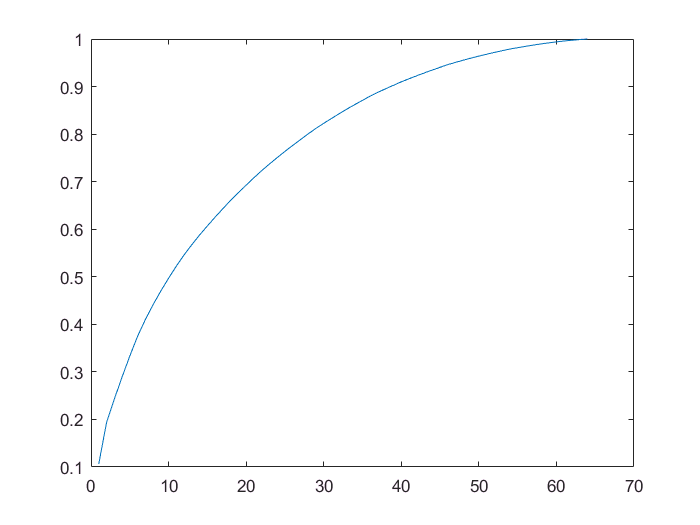

[score_train, score_test, numpc] = pca_getpc(X_train, X_test);


% your code to select new features using PCA-ed data
X_train_pca = score_train(:, 1: numpc);
X_test_pca = score_test(:, 1: numpc);

## auto encoder

epoch 1/50. Average reconstruction error is: 11.698
epoch 2/50. Average reconstruction error is: 6.7184
epoch 3/50. Average reconstruction error is: 5.3354
epoch 4/50. Average reconstruction error is: 4.5372
epoch 5/50. Average reconstruction error is: 4.0865
epoch 6/50. Average reconstruction error is: 3.6944
epoch 7/50. Average reconstruction error is: 3.4514
epoch 8/50. Average reconstruction error is: 3.25
epoch 9/50. Average reconstruction error is: 3.1305
epoch 10/50. Average reconstruction error is: 2.9926
epoch 11/50. Average reconstruction error is: 2.8969
epoch 12/50. Average reconstruction error is: 2.8115
epoch 13/50. Average reconstruction error is: 2.7177
epoch 14/50. Average reconstruction error is: 2.6853
epoch 15/50. Average reconstruction error is: 2.5836
epoch 16/50. Average reconstruction error is: 2.5057
epoch 17/50. Average reconstruction error is: 2.485
epoch 18/50. Average reconstruction error is: 2.4347
epoch 19/50. Average reconstruction error is: 2.3965
epoch

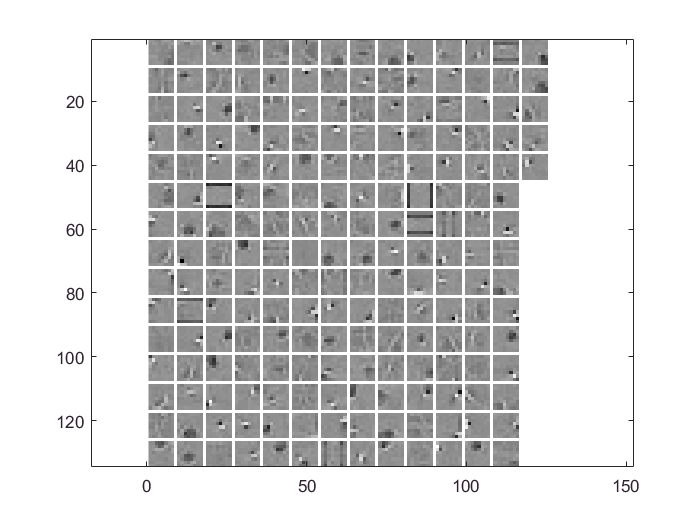

addpath('./DL_toolbox/util','./DL_toolbox/NN','./DL_toolbox/DBN');
 
% your code to train an Auto-encoder, then learn new features from the original data set
% use rbm.m and newFeature_rbm.m
dbn = rbm(X_train);

[X_train_dbn, X_test_dbn] = newFeature_rbm(dbn, X_train, X_test);

## logistic

addpath('./liblinear');
precision_ori_log = logistic(X_train, Y_train, X_test, Y_test);

% your code to train logistic on PCA-ed and Auto-encoder data
precision_pca_log = logistic(X_train_pca, Y_train, X_test_pca, Y_test);
precision_dbm_log = logistic(X_train_dbn, Y_train, X_test_dbn, Y_test);

iter  1 act 1.942e+004 pre 1.737e+004 delta 7.465e-001 f 3.258e+004 |g| 5.275e+004 CG   1
cg reaches trust region boundary
iter  2 act 4.730e+003 pre 3.929e+003 delta 1.125e+000 f 1.316e+004 |g| 1.197e+004 CG   2
cg reaches trust region boundary
iter  3 act 2.791e+003 pre 2.301e+003 delta 1.537e+000 f 8.431e+003 |g| 4.826e+003 CG   3
cg reaches trust region boundary
iter  4 act 1.518e+003 pre 1.205e+003 delta 2.108e+000 f 5.640e+003 |g| 2.612e+003 CG   4
cg reaches trust region boundary
iter  5 act 9.228e+002 pre 7.371e+002 delta 2.902e+000 f 4.122e+003 |g| 1.392e+003 CG   4
cg reaches trust region boundary
iter  6 act 5.300e+002 pre 4.855e+002 delta 3.537e+000 f 3.199e+003 |g| 7.035e+002 CG   4
cg reaches trust region boundary
iter  7 act 3.105e+002 pre 2.749e+002 delta 4.160e+000 f 2.669e+003 |g| 5.198e+002 CG   6
cg reaches trust region boundary
iter  8 act 1.678e+002 pre 1.431e+002 delta 5.098e+000 f 2.359e+003 |g| 3.434e+002 CG   8
cg reaches trust region boundary
iter  9 act 6.08

## kmeans

K = [26, 50];
precision_ori_km = zeros(length(K), 1);
precision_pca_km = zeros(length(K), 1);
precision_dbn_km = zeros(length(K), 1);
for i = 1:length(K)
    k = K(i);
    precision_ori_km(i) = k_means(X_train, Y_train, X_test, Y_test, k);
    
    % your code to train logistic on PCA-ed and Auto-encoder data
    precision_pca_km(i) = k_means(X_train_pca, Y_train, X_test_pca, Y_test, k);
    precision_dbn_km(i) = k_means(X_train_dbn, Y_train, X_test_dbn, Y_test, k);
    
    
    
end